aucC = 0.0717

aucD = 0.0604

aucB = 0.0535

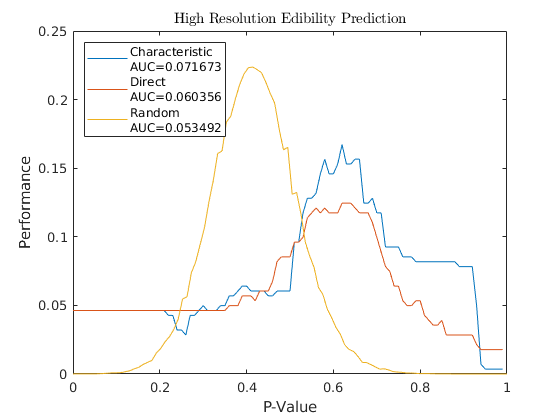

aucC = 0.0795

aucD = 0.0926

aucB = 0.0535

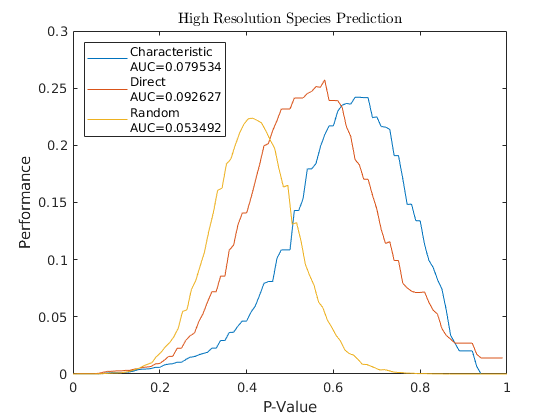

aucC = 0.0723

aucD = 0.0638

aucB = 0.0535

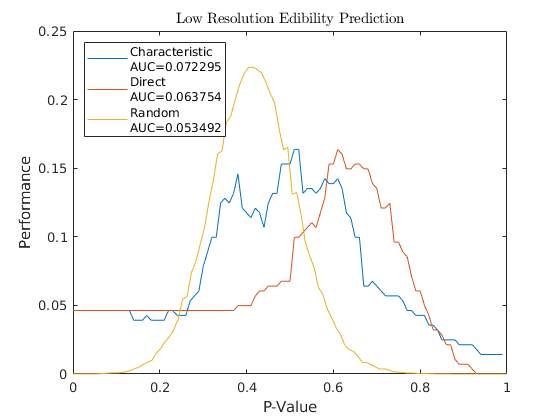

aucC = 0.0875

aucD = 0.1039

aucB = 0.0535

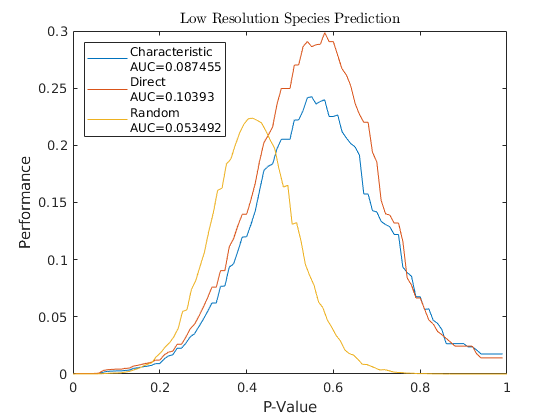

files = dir("performance_data/*_perform.csv");
names = string.empty(length(files), 0);
for i = 1:length(files);
     names(i) = files(i).name;
end
names = names';
cfiles = names(contains(names, "characteristic"));
clen = length('characteristic');
dfiles = names(contains(names, "direct"));
dlen = length('direct');

for i= 1:length(cfiles)
    cf = cfiles(i);
    suffix = cf{1}(clen+1:end);
    df = dfiles(dfiles == "direct" + suffix);
    PC = readmatrix("performance_data/" + cf)';
    PD = readmatrix("performance_data/" + df)';
    PB = readmatrix("performance_data/baseline_perform.csv")';
    
    figure
    plotP(PC, PD, PB, "");
    title(title_from_suffix(suffix))
    saveas(gcf, "plots/" + replace(title_from_suffix(suffix), newline, "") + ".png")
end


PP = readmatrix("performance_data/perfect_perform.csv")';
plot(PP(:,1), PP(:,2));
hold on
plot(PB(:,1), PB(:,2));
hold off
aucP = trapz(PP(:,1), PP(:,2))

aucP = -0.4960

aucB = trapz(PB(:,1), PB(:,2))

aucB = 0.0535

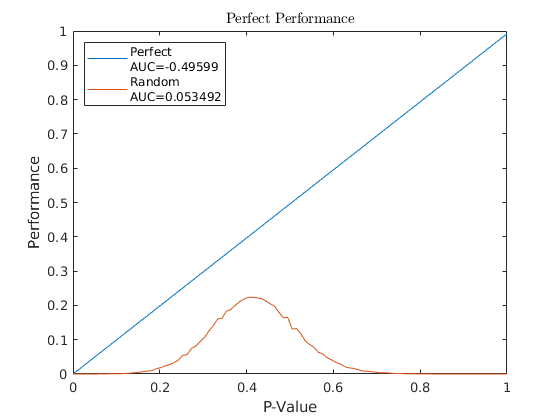

xlabel("P-Value");
ylabel("Performance");
title("Perfect Performance", "Interpreter","latex");
legend("Perfect"+newline+"AUC="+aucP,...
       "Random"+newline+"AUC="+aucB,...
       "Location","northwest")
saveas(gcf, "plots/Perfect Performance.png")

function plotP(PC, PD, PB, name)
    plot(PC(:,1), PC(:,2));
    hold on 
    plot(PD(:,1), PD(:,2));
    plot(PB(:,1), PB(:,2));
    hold off
    xlabel("P-Value");
    ylabel("Performance");
    aucC = trapz(PC(:,1), PC(:,2))
    aucD = trapz(PD(:,1), PD(:,2))
    aucB = trapz(PB(:,1), PB(:,2))
    
    title(name, "Interpreter","latex");
    legend(["Characteristic"+newline+"AUC="+aucC, ...
        "Direct"+newline+"AUC="+aucD,...
        "Random"+newline+"AUC="+aucB,...
        ], "Location","northwest")
end
function tit = title_from_suffix(suffix)
    tit = "";
    suffix = string(suffix);
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    else
        tit = tit + " Species Prediction";
    end
end